clc
clear
close all

% 1. Ukol - Konstanta + charakterisitka

ot = -2000:250:2000;
U = [-3.9757 -3.4787 -2.9858 -2.4873 -1.9902 -1.4922 -0.99557 -0.50150 -0.000092 0.50022 1.0033 1.5076 2.0117 2.5144 2.9930 3.4802 3.9793];

[K, U0] = metoda_nejm_ctvercu(ot, U);

c = 0.0827

d = 25500000

e = 0

(0.001993-0.002)/0.002 * 100

ans = -0.3500

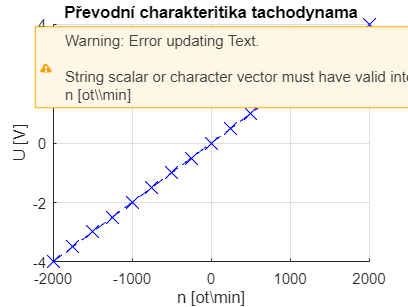


U_aprox = K.*ot + U0;
deltal = max(linearity(U, U_aprox) * 100); 
%Max je pro 14
figure(1)
    hold on;
    grid on;
    plot(ot, U, 'x', markersize=12, MarkerEdgeColor='b');
    plot(ot, U_aprox, '--b')
    % Dodelat popisky, atd...
    xlabel("n [ot\min]")
    ylabel("U [V]")
    title("Převodní charakteritika tachodynama")
    legend("Naměřené body", "Lineární regrese MNČ")

    hold off;